# Machine learning diagnostic

Implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. 

Then use some diagnostics of debugging learning algorithms and examine the effects of bias v.s. variance.

## 1 Loading and Visualizing Data

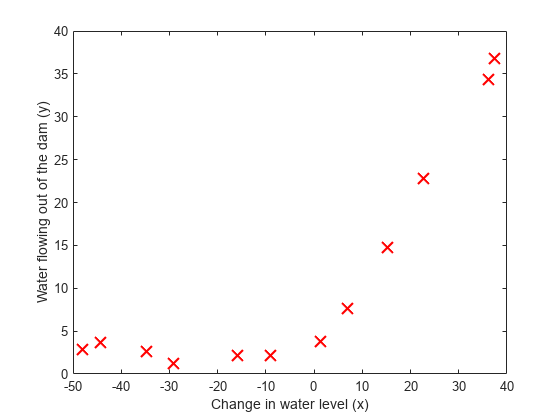

clear; 
close all; 
clc;

load ('ex5data1.mat');
m = size(X, 1);
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

## 2 Train Linear Regression

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01


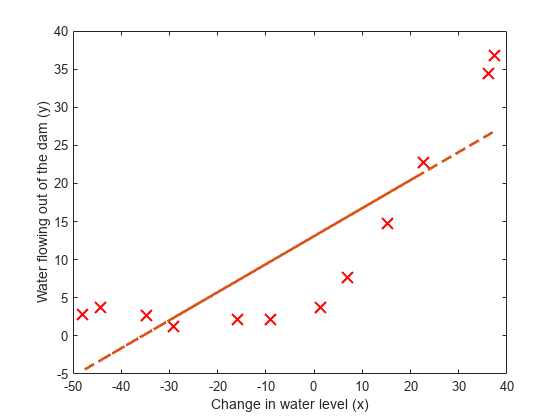

%  Plot fit over the data
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

**Learning Curve for Linear Regression**

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

Iteration     1 | Cost: 2.663868e-01
Iteration     2 | Cost: 3.944305e-31
Iteration     3 | Cost: 0.000000e+00
Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.332343e-30
Iteration     3 | Cost: 9.860761e-32
Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00
Iteration     3 | Cost: 3.286595e+00
Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 2.842724e+00
Iteration     7 | Cost: 2.842689e+00
Iteration     8 | Cost: 2.842686e+00
Iteration     9 | Cost: 2.842678e+00
Iteration    10 | Cost: 2.842678e+00
Iteration    11 | Cost: 2.842678e+00
Iteration    12 | Cost: 2.842678e+00
Iteration    13 | Cost: 2.842678e+00
Iteration     1 | Cost: 1.592641e+02
Iteration     2 | Cost: 2.404966e+01
Iteration     3 | Cost: 2.354137e+01
Iteration     4 | Cost: 2.281160e+01
Iteration     5 | Cost: 2.276969e+01
I

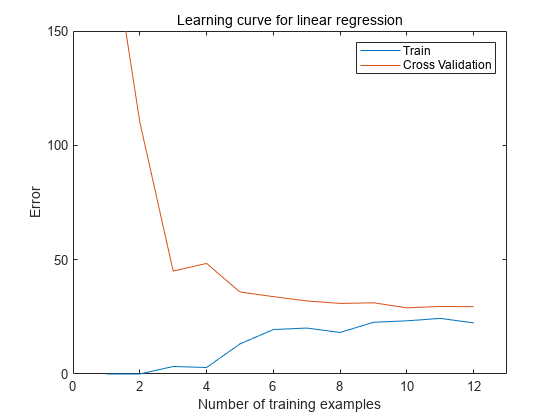

plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])

## 3 Feature Mapping for Polynomial Regression

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = bsxfun(@minus, X_poly_test, mu);
X_poly_test = bsxfun(@rdivide, X_poly_test, sigma);
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = bsxfun(@minus, X_poly_val, mu);
X_poly_val = bsxfun(@rdivide, X_poly_val, sigma);
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

**Learning Curve for Polynomial Regression**

lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411684e-01
Iteration    11 | Cost: 7.995244e-01
Iteration    12 | Cost: 7.577869e-01
Iteration    13 | Cost: 6.711064e-01
Iteration    14 | Cost: 4.869993e-01
Iteration    15 | Cost: 4.453758e-01
Iteration    16 | Cost: 4.419455e-01
Iteration    17 | Cost: 4.366545e-01
Iteration    18 | Cost: 4.349488e-01
Iteration    19 | Cost: 4.274097e-01
Iteration    20 | Cost: 4.248393e-01
Iteration    21 | Cost: 4.241510e-01
Iteration    22 | Cost: 4.115683e-01
Iteration    23 | Cost: 3.590926e-01
Iteration    24 | Cost: 3.566797e-01
Iteration    25 | Cost: 3.532088e-01
Iteration    26 | Cost: 3.517908e-01
Iteration    27 | Cost: 3.454821e-01
I

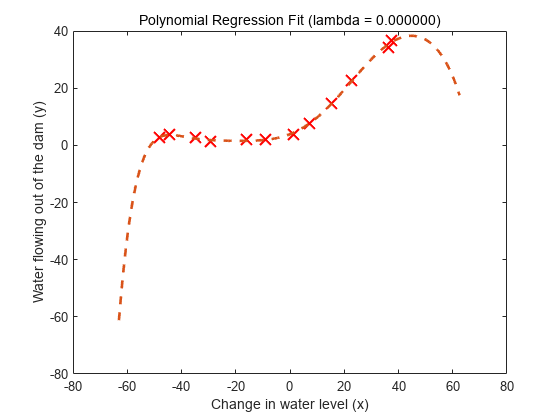

% Plot training data and fit
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 3.386454e-01
Iteration     2 | Cost: 9.860761e-32
Iteration     4 | Cost: 0.000000e+00
Iteration     1 | Cost: 5.373343e-02
Iteration     2 | Cost: 2.656989e-04
Iteration     3 | Cost: 1.480972e-05
Iteration     4 | Cost: 1.420517e-11
Iteration     5 | Cost: 7.255780e-12
Iteration     6 | Cost: 1.293770e-14
Iteration     7 | Cost: 1.291564e-14
Iteration     8 | Cost: 6.787523e-15
Iteration     9 | Cost: 4.423133e-16
Iteration    10 | Cost: 2.255088e-16
Iteration    11 | Cost: 1.041959e-18
Iteration    12 | Cost: 2.733926e-19
Iteration    13 | Cost: 3.946247e-21
Iteration    14 | Cost: 6.162976e-32
Iteration    15 | Cost: 0.000000e+00
Iteration     1 | Cost: 3.023381e+01
Iteration     2 | Cost: 9.745401e-01
Iteration     3 | Cost: 4.827305e-01
Iteration     4 | Cost: 1.170249e-02
Iteration     5 | Cost: 9.696908e-04
Iteration     6 | Cost: 5.299258e-04
Iteration     7 | Cost: 1.985836e-04
Iteration     8 | Cost: 6.032119e-05
Iteration     9 | Cost: 6.225212e-07
I

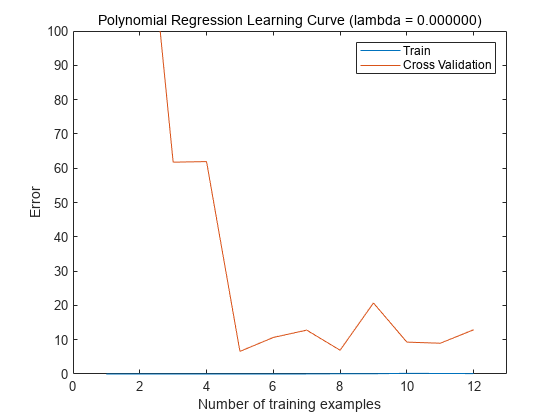

figure;
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

## 4 Validation for Selecting Lambda

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411684e-01
Iteration    11 | Cost: 7.995244e-01
Iteration    12 | Cost: 7.577869e-01
Iteration    13 | Cost: 6.711064e-01
Iteration    14 | Cost: 4.869993e-01
Iteration    15 | Cost: 4.453758e-01
Iteration    16 | Cost: 4.419455e-01
Iteration    17 | Cost: 4.366545e-01
Iteration    18 | Cost: 4.349488e-01
Iteration    19 | Cost: 4.274097e-01
Iteration    20 | Cost: 4.248393e-01
Iteration    21 | Cost: 4.241510e-01
Iteration    22 | Cost: 4.115683e-01
Iteration    23 | Cost: 3.590926e-01
Iteration    24 | Cost: 3.566797e-01
Iteration    25 | Cost: 3.532088e-01
Iteration    26 | Cost: 3.517908e-01
Iteration    27 | Cost: 3.454821e-01
I

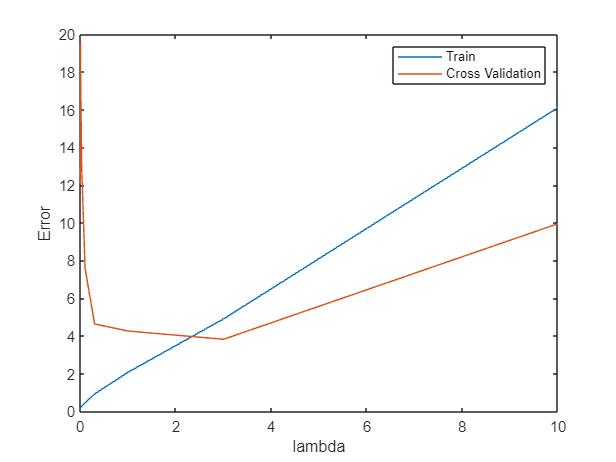

plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

**Computing test set error**

[min_err, idx] = min(error_val);
lambda = lambda_vec(idx);
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.416707e+01
Iteration     2 | Cost: 3.345965e+01
Iteration     3 | Cost: 2.112694e+01
Iteration     4 | Cost: 1.621542e+01
Iteration     5 | Cost: 1.605198e+01
Iteration     6 | Cost: 1.596514e+01
Iteration     7 | Cost: 1.596285e+01
Iteration     8 | Cost: 1.592089e+01
Iteration     9 | Cost: 1.589157e+01
Iteration    10 | Cost: 1.589011e+01
Iteration    11 | Cost: 1.587849e+01
Iteration    12 | Cost: 1.587363e+01
Iteration    13 | Cost: 1.586793e+01
Iteration    14 | Cost: 1.586791e+01
Iteration    15 | Cost: 1.586776e+01
Iteration    16 | Cost: 1.586772e+01
Iteration    17 | Cost: 1.586769e+01
Iteration    18 | Cost: 1.586769e+01
Iteration    19 | Cost: 1.586769e+01
Iteration    20 | Cost: 1.586769e+01
Iteration    21 | Cost: 1.586769e+01
Iteration    22 | Cost: 1.586769e+01
Iteration    23 | Cost: 1.586769e+01
Iteration    24 | Cost: 1.586769e+01
Iteration    25 | Cost: 1.586769e+01
Iteration    26 | Cost: 1.586769e+01
Iteration    27 | Cost: 1.586769e+01
I

[J_test, grad] = linearRegCostFunction(X_poly_test, ytest, theta, 0);   % lambda = 0 when calculate training error
fprintf('lambda=%f, test_error = %f\n', lambda, J_test);

lambda=3.000000, test_error = 3.859888


**Plotting learning curves with randomly selected examples**

lambda = 3.0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.416707e+01
Iteration     2 | Cost: 3.345965e+01
Iteration     3 | Cost: 2.112694e+01
Iteration     4 | Cost: 1.621542e+01
Iteration     5 | Cost: 1.605198e+01
Iteration     6 | Cost: 1.596514e+01
Iteration     7 | Cost: 1.596285e+01
Iteration     8 | Cost: 1.592089e+01
Iteration     9 | Cost: 1.589157e+01
Iteration    10 | Cost: 1.589011e+01
Iteration    11 | Cost: 1.587849e+01
Iteration    12 | Cost: 1.587363e+01
Iteration    13 | Cost: 1.586793e+01
Iteration    14 | Cost: 1.586791e+01
Iteration    15 | Cost: 1.586776e+01
Iteration    16 | Cost: 1.586772e+01
Iteration    17 | Cost: 1.586769e+01
Iteration    18 | Cost: 1.586769e+01
Iteration    19 | Cost: 1.586769e+01
Iteration    20 | Cost: 1.586769e+01
Iteration    21 | Cost: 1.586769e+01
Iteration    22 | Cost: 1.586769e+01
Iteration    23 | Cost: 1.586769e+01
Iteration    24 | Cost: 1.586769e+01
Iteration    25 | Cost: 1.586769e+01
Iteration    26 | Cost: 1.586769e+01
Iteration    27 | Cost: 1.586769e+01
I

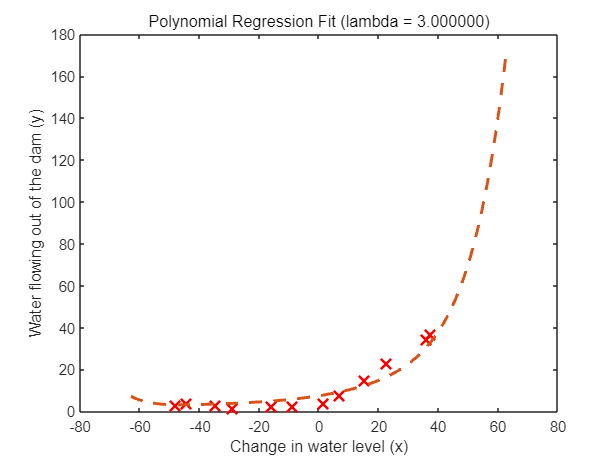

figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurveWithRandomSel(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 2.611335e+00
Iteration     2 | Cost: 7.089194e-02
Iteration     3 | Cost: 2.646710e-02
Iteration     4 | Cost: 1.244898e-04
Iteration     5 | Cost: 4.647757e-05
Iteration     6 | Cost: 7.829154e-11
Iteration     7 | Cost: 6.400350e-11
Iteration     8 | Cost: 1.010463e-12
Iteration     9 | Cost: 1.422954e-17
Iteration    10 | Cost: 9.306614e-28
Iteration    11 | Cost: 9.116440e-32
Iteration    12 | Cost: 4.266128e-36
Iteration    13 | Cost: 1.237256e-38
Iteration    14 | Cost: 2.428238e-50
Iteration    15 | Cost: 4.765659e-62
Iteration    16 | Cost: 9.353080e-74
Iteration    17 | Cost: 1.835635e-85
Iteration    18 | Cost: 3.602617e-97
Iteration    19 | Cost: 7.070495e-109
Iteration    20 | Cost: 1.387655e-120
Iteration    21 | Cost: 2.723411e-132
Iteration    22 | Cost: 5.344966e-144
Iteration    23 | Cost: 1.049003e-155
Iteration    24 | Cost: 2.058772e-167
Iteration    25 | Cost: 4.040546e-179
Iteration    26 | Cost: 7.929974e-191
Iteration    27 | Cost: 1.5563

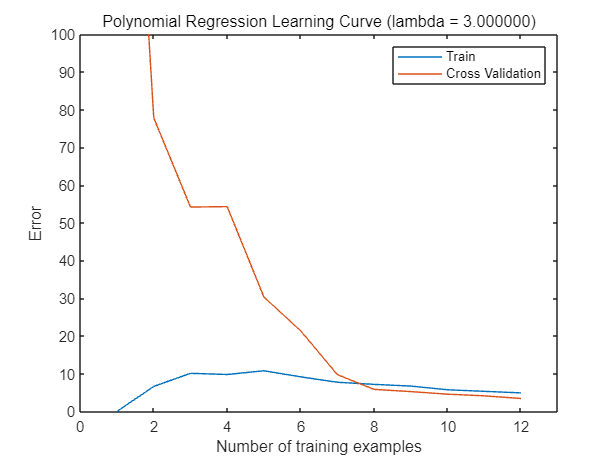

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

## 5 Function

function [J, grad] = linearRegCostFunction(X, y, theta, lambda)
%LINEARREGCOSTFUNCTION Compute cost and gradient for regularized linear 
%regression with multiple variables
%   [J, grad] = LINEARREGCOSTFUNCTION(X, y, theta, lambda) computes the 
%   cost of using theta as the parameter for linear regression to fit the 
%   data points in X and y. Returns the cost in J and the gradient in grad
    m = length(y); 
    
    J = (X*theta-y)'*(X*theta-y)/(2*m) + lambda/(2*m)*theta(2:end,:)'*theta(2:end,:);
    
    grad_reg = zeros(size(theta));
    grad_reg(2:end) = lambda/m*theta(2:end,:);
    grad = X'*(X*theta-y)./m + grad_reg;
    
    grad = grad(:);
end

function [theta] = trainLinearReg(X, y, lambda)
%TRAINLINEARREG Trains linear regression given a dataset (X, y) and a
%regularization parameter lambda
%   [theta] = TRAINLINEARREG (X, y, lambda) trains linear regression using
%   the dataset (X, y) and regularization parameter lambda. Returns the
%   trained parameters theta.
%
    % Initialize Theta
    initial_theta = zeros(size(X, 2), 1); 
    
    % Create "short hand" for the cost function to be minimized
    costFunction = @(t) linearRegCostFunction(X, y, t, lambda);
    
    % Now, costFunction is a function that takes in only one argument
    options = optimset('MaxIter', 200, 'GradObj', 'on');
    
    % Minimize using fmincg
    theta = fmincg(costFunction, initial_theta, options);
end

function [error_train, error_val] = ...
    learningCurve(X, y, Xval, yval, lambda)
%LEARNINGCURVE Generates the train and cross validation set errors needed 
%to plot a learning curve
%   [error_train, error_val] = ...
%       LEARNINGCURVE(X, y, Xval, yval, lambda) returns the train and
%       cross validation set errors for a learning curve. In particular, 
%       it returns two vectors of the same length - error_train and 
%       error_val. Then, error_train(i) contains the training error for
%       i examples (and similarly for error_val(i)).
%
%   In this function, you will compute the train and test errors for
%   dataset sizes from 1 up to m. In practice, when working with larger
%   datasets, you might want to do this in larger intervals.
%
    m = size(X, 1);
    
    % You need to return these values correctly
    error_train = zeros(m, 1);
    error_val   = zeros(m, 1);
    
    for i = 1:m
        [theta] = trainLinearReg(X(1:i, :), y(1:i), lambda);
        [error_train(i), ~] = linearRegCostFunction(X(1:i, :), y(1:i), theta, 0);
        [error_val(i), ~] = linearRegCostFunction(Xval, yval, theta, 0);
    end
end

function [X_poly] = polyFeatures(X, p)
%POLYFEATURES Maps X (1D vector) into the p-th power
%   [X_poly] = POLYFEATURES(X, p) takes a data matrix X (size m x 1) and
%   maps each example into its polynomial features where
%   X_poly(i, :) = [X(i) X(i).^2 X(i).^3 ...  X(i).^p];
%
    X_poly = zeros(numel(X), p);
    for i=1:p
        X_poly(:, i) = X.^i;
    end
end

function [X_norm, mu, sigma] = featureNormalize(X)
%FEATURENORMALIZE Normalizes the features in X 
%   FEATURENORMALIZE(X) returns a normalized version of X where
%   the mean value of each feature is 0 and the standard deviation
%   is 1. This is often a good preprocessing step to do when
%   working with learning algorithms.
    mu = mean(X);
    X_norm = bsxfun(@minus, X, mu);
    
    sigma = std(X_norm);
    X_norm = bsxfun(@rdivide, X_norm, sigma);
end

function plotFit(min_x, max_x, mu, sigma, theta, p)
%PLOTFIT Plots a learned polynomial regression fit over an existing figure.
%Also works with linear regression.
%   PLOTFIT(min_x, max_x, mu, sigma, theta, p) plots the learned polynomial
%   fit with power p and feature normalization (mu, sigma).
    % Hold on to the current figure
    hold on;
    
    % We plot a range slightly bigger than the min and max values to get
    % an idea of how the fit will vary outside the range of the data points
    x = (min_x - 15: 0.05 : max_x + 25)';
    
    % Map the X values 
    X_poly = polyFeatures(x, p);
    X_poly = bsxfun(@minus, X_poly, mu);
    X_poly = bsxfun(@rdivide, X_poly, sigma);
    
    % Add ones
    X_poly = [ones(size(x, 1), 1) X_poly];
    
    % Plot
    plot(x, X_poly * theta, '--', 'LineWidth', 2)
    
    % Hold off to the current figure
    hold off
end

function [lambda_vec, error_train, error_val] = validationCurve(X, y, Xval, yval)
%VALIDATIONCURVE Generate the train and validation errors needed to
%plot a validation curve that we can use to select lambda
%   [lambda_vec, error_train, error_val] = ...
%       VALIDATIONCURVE(X, y, Xval, yval) returns the train
%       and validation errors (in error_train, error_val)
%       for different values of lambda. You are given the training set (X,
%       y) and validation set (Xval, yval).
%
% Selected values of lambda (you should not change this)
    lambda_vec = [0 0.001 0.003 0.01 0.03 0.1 0.3 1 3 10]';
    
    % You need to return these variables correctly.
    error_train = zeros(length(lambda_vec), 1);
    error_val = zeros(length(lambda_vec), 1);
    
    for i = 1:length(lambda_vec)
        [theta] = trainLinearReg(X, y, lambda_vec(i));
        [error_train(i), ~] = linearRegCostFunction(X, y, theta, 0);
        [error_val(i), ~] = linearRegCostFunction(Xval, yval, theta, 0);
    end
end

function [error_train, error_val] = learningCurveWithRandomSel(X, y, Xval, yval, lambda)
%LEARNINGCURVE Generates the train and cross validation set errors needed 
%to plot a learning curve
%   [error_train, error_val] = ...
%       LEARNINGCURVE(X, y, Xval, yval, lambda) returns the train and
%       cross validation set errors for a learning curve. In particular, 
%       it returns two vectors of the same length - error_train and 
%       error_val. Then, error_train(i) contains the training error for
%       i examples (and similarly for error_val(i)).
%
%   In this function, you will compute the train and test errors for
%   dataset sizes from 1 up to m. In practice, when working with larger
%   datasets, you might want to do this in larger intervals.
%

    % Number of training examples
    m = size(X, 1);
    
    % You need to return these values correctly
    error_train = zeros(m, 1);
    error_val   = zeros(m, 1);
    
    k = size(Xval, 1);
    for i=1:m
      ki = min(i,k);
      sum_train_J = 0;
      sum_val_J = 0;
      
      for j=1:50
		    % Randomly select i data 
		    rand_indices = randperm(m);
		    X_sel = X(rand_indices(1:i), :);
		    y_sel = y(rand_indices(1:i), :);
		    
		    [theta] = trainLinearReg(X_sel, y_sel, lambda);
		    [J, ~] = linearRegCostFunction(X_sel, y_sel, theta, 0);  
		    sum_train_J = sum_train_J + J;
		    
		    rand_indices = randperm(k);
		    Xval_sel = Xval(rand_indices(1:ki), :);
		    yval_sel = yval(rand_indices(1:ki), :);
		    [J, ~] = linearRegCostFunction(Xval_sel, yval_sel, theta, 0); 
		    sum_val_J = sum_val_J + J;
      end
      error_train(i) = sum_train_J/50;
      error_val(i) = sum_val_J/50;
    end

end